## Week 5 - Part 1

Dave Hill - Oregon State University

Ok. So, we have learned our way around Matlab. We can store information in lots of ways, we can do a number of calculations, and we can even import / export data. Cool. But, if you want to share your information with other people, you need to do it visually. Tables of numbers don't tell a good story...well constructed and thoughtful graphics do. This is a very brief introduction, out of necessity...graphics in Matlab are a HUGE topic, so this is just a quick tour of some of the basics. However, some working principles to keep in mind:

- Use color carefully. It should be a 'supporting role' and not dominate.

- Minmize text. Tell your story visually to the extent possible.

- Keep it simple...make a single point with each figure.

- No one likes a crowd...strategic use of white / empty space can be an asset.

The web is [FULL](https://www.biostat.wisc.edu/~kbroman/topten_worstgraphs/) of examples of bad and good figures. Take some time to critically look at figures and note what works for you and what does not.

## Line Plots

Perhaps the simplest way to represent data is with a line plot. One variable against another...Below is an example. Note the use of various labeling commands.

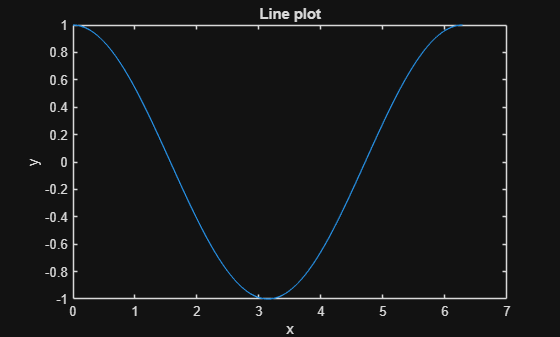

figure(1)
x=linspace(0,2*pi,100);
y=cos(x);
plot(x,y);
xlabel('x');ylabel('y');title('Line plot');

Subplot is a nice way of placing several axes on the same figure. In this example, I will create a 3 x 1 subplot, and plot different things in each subpanel. I am going to use section breaks so that we can talk about things one subpanel at a time. Here, in the first subpanel, I show you how to superimpose two plots with 'hold.' I also show you how you can control line color and line width. Finally, note the ability to add a legend, which is always a good idea when you are plotting more than one thing.

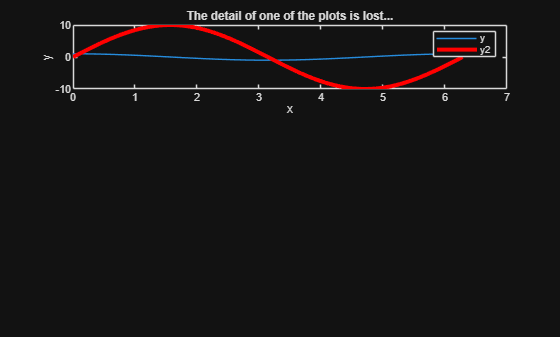

figure(2)
y2=10*sin(x);
subplot(3,1,1)  %let us superimpose two plots with the hold command.
plot(x,y); hold on
plot(x,y2,'r','Linewidth',3)    %note my use of 'options' (there are many)
xlabel('x');ylabel('y');
legend('y','y2');   %NEVER make a plot (multiline) w/o a legend!
title('The detail of one of the plots is lost...');

In that first subplot, you can see that the results are not very satisfactory in the sense that we don't see the variation in the blue line very clearly. You can use the plotyy command when you wish to plot two things with very different scales.

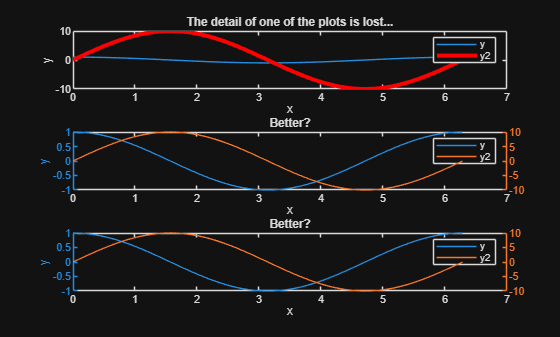

subplot(3,1,2)
plotyy(x,y,x,y2); %note the different line and axis colors. You can adjust these if you wish.
xlabel('x');ylabel('y');
legend('y','y2');
title('Better?')

Shoot...when we do this, it becomes a bit tricky to label the second y-axis. Matlab's 'ylabel' command operates only on the left y axis. What to do? Well, there is this WHOLE topic in Matlab called 'handle' graphics. Check out my syntax below. By having a variable name and equals sign to left of a graphics command (such as plotyy) we get a 'handle' or identifier. And then, we can start to modify things using command line commands.

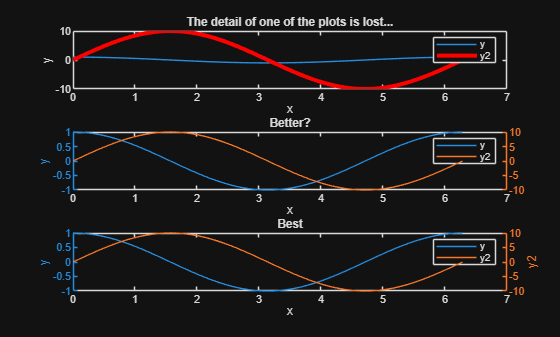

%Note. How to label the 2nd y axis?
subplot(3,1,3)
[ax h1 h2]=plotyy(x,y,x,y2);    %ax --> handles of the two axes; h1/h2 --> handles of the individual lines.
xlabel('x');ylabel('y');
legend('y','y2');
axes(ax(2));ylabel('y2');   %axes command is making 2nd y axis 'current'
title('Best')

Ok, so that worked...what exactly did I do? Let's begin by exploring what is in 'ax.' Ax is the 'handle' of the plot axes. There are two entries since we used plotyy. For a simple plot command, ax would only have one entry

ax

ax =   1×2 Axes array:

    Axes    Axes


ax(1)

ans =   Axes with properties:

             XLim: [0 7]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1366 0.7750 0.1718]
            Units: 'normalized'

  Show all properties


ax(2)

ans =   Axes (Best) with properties:

             XLim: [0 7]
             YLim: [-10 10]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1366 0.7750 0.1718]
            Units: 'normalized'

  Show all properties


You see all the information that is stored in there? Now the command (used above)

>>axes(ax(2))

essentially makes the 'second' axis the 'active' one. So, when I issue the ylabel command after that, it labels the second axis.

Let's close this section by looking at what is in h1 and h2

h1

h1 =   Line (y) with properties:

              Color: [0.1490 0.5490 0.8660]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0635 0.1269 0.1904 0.2539 0.3173 0.3808 0.4443 0.5077 0.5712 0.6347 0.6981 0.7616 0.8251 0.8885 0.9520 1.0155 1.0789 1.1424 1.2059 1.2693 1.3328 1.3963 1.4597 1.5232 1.5867 1.6501 1.7136 1.7771 1.8405 1.9040 … ] (1×100 double)
              YData: [1 0.9980 0.9920 0.9819 0.9679 0.9501 0.9284 0.9029 0.8738 0.8413 0.8053 0.7660 0.7237 0.6785 0.6306 0.5801 0.5272 0.4723 0.4154 0.3569 0.2969 0.2358 0.1736 0.1108 0.0476 -0.0159 -0.0792 -0.1423 -0.2048 -0.2665 … ] (1×100 double)

  Show 

h2

h2 =   Line (y2) with properties:

              Color: [0.9600 0.4660 0.1600]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0635 0.1269 0.1904 0.2539 0.3173 0.3808 0.4443 0.5077 0.5712 0.6347 0.6981 0.7616 0.8251 0.8885 0.9520 1.0155 1.0789 1.1424 1.2059 1.2693 1.3328 1.3963 1.4597 1.5232 1.5867 1.6501 1.7136 1.7771 1.8405 1.9040 … ] (1×100 double)
              YData: [0 0.6342 1.2659 1.8925 2.5115 3.1203 3.7166 4.2979 4.8620 5.4064 5.9291 6.4279 6.9008 7.3459 7.7615 8.1458 8.4973 8.8145 9.0963 9.3415 9.5490 9.7181 9.8481 9.9384 9.9887 9.9987 9.9685 9.8982 9.7880 9.6384 9.4500 … ] (1×100 double)

  Show 

### Controlling Appearance via the Editor

Matlab allows you to change almost anything you want about how the figure looks. We saw a bit of this above when we adjusted the line width. You can do this is one of two ways: (1) Edit Figure/Axis properties; (2) 'set' command. A good reference is: [http://www.mathworks.com/help/matlab/ref/axes_props.html.](http://www.mathworks.com/help/matlab/ref/axes_props.html.)

Let's go back to Figure 1. In the figure below, click on the arrow in the upper right hand corner and it will open up as a separate figure outside of this live script. Now choose 'edit - figure properties.' Note that you can adjust things like the background color, etc (expand the menu options in the property editor). You will NOT see anything having to do with the particular figure axes. To see that, select 'edit - axes properties'. Select 'more properties.' You can, for example, scroll down to font name / size and adjust them. Try it. Note that the labels / title will also change. To change those DIRECTLY, click on the title (or an axis label). Note that the 'Inspector' changes from 'axes' to 'text' when you do this. Click back on the axes. Scroll down to 'Tick Dir' and try changing it. The sky is the limit, in terms of what you can change. When you are done, close the figure.

figure(3);
plot(x,y); xlabel('x stuff'); ylabel('y stuff'); title('sample plot')

With a multi-panel plot (like Fig 2 above), if you open up the figure and edit the axes, note that you can control the appearance of each axis separately. Close the figure when you are done.

You need to think about Matlab figures as a hierarchy. The highest level 'thing' is the figure itself. In that figure, you can have multiple axes (say, if you are using subplot). On each axis, you have several 'things' in terms of multiple lines being plotted, etc. Let's see a list of all of the 'things' ('properties' is the official term) that exist for our figure:

get(gcf)

And, let's see a list of the properties for the one axis in this figure

get(gca)

Here is the bottom line: DON'T USE THE EDITOR

### Controlling Appearance via Handle Graphics

We got introduced to handle graphics up above, when we had to figure out to label the second y axis when we used the plotyy command. To be honest, editing figures like we did immediately above, using the various editors, is a really inefficient way of doing things. You can control every thing that you need to  via handle graphics commands, coded directly into your scripts. Let's look a bit deeper into this... 

figure(3)
h=plot(x,y,'o');
set(h,'Color','red');  %so 'h' is the handle of the x-y plot.
set(h,'markers',50);   %we can change size / color / etc. of this plot feature.

Note how I usd the 'set' command on the h handle (which is the handle of the plotted data) to change size and color. Now, let's label the xaxis, but assign it to a different handle. And, once we have done that, let's change some things.

h2=xlabel('A Label for the x Axis'); 
set(h2,'FontSize',24,'Color','red')

Finally, let us use the set command on the entire axis (we saw gca above) and change all fonts.

set(gca,'FontName','Times') %this changes tick labels and x axis label.

Note: there are other ways to change the color (and other parameters) by using 'dot' notation.

h.Color = 'green';
h.MarkerSize=20;
h.LineWidth=5;
h.MarkerFaceColor='blue';

Can also use hexadecimal codes

h.Color = '#FFC0CB';

### 3d Line Plots

All of our plots above were 2d; easy to do 3d line plots!

clear all
close all
t=linspace(0,4*pi,200);
x=cos(t);
y=sin(t);
figure(1)
plot3(x,y,t);
grid on
hold on
plot3(x,y,t,'r.')
xlabel('x');ylabel('y');zlabel('t');
title('simple 3d line plot')

We can also do scatter plots (either 3d or 2d). This is a great way of plotting points with their colors set by some property.

figure(2)
hold off
scatter3(x,y,t,10,t,'filled')  %here the value of the variable t determines color.
xlabel('x');ylabel('y');zlabel('t');
title('Color based on z data value')
[AZ,EL]=view

Note these figures are 'perspective' figures, as we are looking at 3d information. You can control view angle. First, what is the angle? Above, I used the the view command to dump out the azimuth and elevation angles. Click on the arrow at upper right of the figure to open it outside of the live editor. Then click on the 'rotate' button at the top of the axes. You can see that you can rotate the figure around. Some views are great, some are terrible. It can take some trial and error to determine the best view. Note also that you can 'set' the view

Here we simply use the view command to change the view.

figure(3)
scatter3(x,y,t,10,t,'filled')
xlabel('x');ylabel('y');zlabel('t');
AZnew=60; ELnew=80;
view([AZnew,ELnew]); 

## In-Class Exercise

Let's take a break and do some hands-on work. Head over [here](https://github.com/dfosterhill/matlab_class/blob/main/scripts/week5/student_example1.md) for the details. We will come back to this live script in a bit...

## Surface Plots

Ok, so all of the previous plots have been simple vectors of data that we wanted to plot, either in 2 or 3 dimensions. Another common plotting application is when we have a 'grid' of data that we want to show. There are SO many ways of doing this in Matlab. Many of them require that you have matrices of X and Y values so that the axes properly show the coordinates and not just integer values (1st row, second, etc.). Let's start with the surf (surface) command.

clear all
close all
clc
[X,Y]=meshgrid(linspace(-4,4,40),linspace(-4,4,40)); %X and Y are now matrices...
Z=peaks(X,Y);
figure(1)
surf(X,Y,Z);
xlabel('x');ylabel('y');title('surf - default')

Huh. Well, we definintely see something. We see some peaks, some troughs, and so on. We also see black lines that basically show you the borders of the individual cells. If you have too many cells, those black lines will overwhelm the figure. Let's turn 'em off! In this case, each cell is colored according to the value in that cell. This will look good if the cells are fairly small. It can look clunky if you have really large cells.

figure(2)
surf(X,Y,Z); 
shading flat
xlabel('x');ylabel('y');title('surf - flat')

Yet another option is to smoothly interpolate the colors over the cells.

figure(3)
surf(X,Y,Z); 
shading interp  %here we get a nice smooth transition.
xlabel('x');ylabel('y');title('surf - interp')


So, some people love 3d plots, others don't. And, that's ok. Displaying complex data is an art, and everyone has different tastes. There is one nice variant of this surf command that places 2d contour lines on the bottom of the 3d view to help in visual interpretation.

figure(4)
surfc(X,Y,Z); 
shading interp
xlabel('x');ylabel('y');title('surfc')  %note contours on bottom!

At this point, the sky is the limit, in terms of you can take figures as far as you want. I like this shadowplot option (function is from the file exchange online). Basically, it's like shining a light and creating a silhouette on each vertical plane. Very informative.

figure(5)
surf(X,Y,Z);shading interp; hold on
shadowplot x
shadowplot y

## Contour Lines

Sometimes 3d plots are simply too cluttered, visually. And, sometimes less is just more. Contour lines are a great way to visualize data. If you have ever looked at a topographic map on a hike, you 100% know what contour lines are. And...we just saw one example of contour lines above.

clear all
close all
[X,Y]=meshgrid(linspace(-4,4,100),linspace(-4,4,100));
Z=peaks(X,Y);
figure(1)
contour(X,Y,Z);
colorbar;
title('standard contour');

Ok, that looks pretty good. The default is a set of lines that are colored by the value of the variable whose contour lines you are plotting. Here's another way to do it:

figure(2)
contourf(X,Y,Z);title('standard contour')

Now, when you make contour plots, Matlab tries to figure out the best 'balance' of contour levels to plot. And, usually, it is pretty good at doing this. However, Matlab may choose weird (not round) numbers. If you want to specify the contour levels to plot, you can totally do that. Again, think of a topographic map...contours are placed at nice round numbers, right?

figure(3)
contourf(X,Y,Z,[-8:1:8]);title('contourf at specified levels');
colorbar

And, sure, we can add a colorbar to this (above), but some people prefer to put labels on the figure itself, showing the values of the lines. This is precisely what is done on a topo map. Note that the output of this can be a little unpredictable...

figure(4)
[c,h]=contour(X,Y,Z,[-8 -2 0 2 8],'k');title('labeled') %labels 
clabel(c,h)

## Scattered Data

Things can be a bit more complex with scattered data! As one application, finite element meshes are not on 'regular' grids.  However, they are not just collections of scattered points.  A 'triangulation' exists that specifies which nodes form which (usually) triangular elements. Now, for plotting you COULD just interpolate your results back onto a regular grid. BUT, that defeats the purpose of the finite element in the first place! For this example, I will use matlab's delaunay triangulation routine to connect scattered points. Below, I make use of a file exchange program called tricontour. It is at:

[https://www.mathworks.com/matlabcentral/fileexchange/38858-contour-plot-for-scattered-data](https://www.mathworks.com/matlabcentral/fileexchange/38858-contour-plot-for-scattered-data) 

clear all
close all
load seamount %this is just x, y, z (depth) triplets of data.
tri=delaunay(x,y); %this performs the triangulation process.
tri(1:5,:)

%first, let's make a scatter plot showing location of the data.

figure(1)
scatter(x,y,20,z,'filled'); colorbar;

%We can easily add contours. NOTE. for scattered data, you need to get the
%tricontour mfile from the online file exchange

hold on
contours=[-4000 -3000 -2000 -1000];
[c,h]=tricontour(tri,x,y,z,contours);
clabel(c);


It can also be nice to make surface plots of scattered, triangulated data. Use shading flat or shading interp (as we did above) to adjust the results to your liking.

figure(2)
trisurf(tri,x,y,z); 
view(0,90); %to get top view
shading interp;   %to remove black lines...

Now, superimposing contours on a surface plot is tricky.  Below, we execute the call, but you will note that we don't see anything, since the contours lines are given the same colormap. If we change change the view (click on arrow in upper right of figure, and experiment with the rotation yourself, and you will see the contours! They are placed in the z = 0 plane).

figure(3)
trisurf(tri,x,y,z); 
view(0,90); %to get top view
shading interp;   %to remove black lines...
hold on
contours=[-4000 -3000 -2000 -1000];
[c,h]=tricontour(tri,x,y,z,contours);
clabel(c);

With triangulated contours it is really tricky to set the contour lines to be a uniform color (like black). This is easy with 'regular' (gridded) data. Below is my attempt to arrive at a solution. It works, but it is ugly. Maybe one of you can find a better solution and let me know about it!

figure(4)
trisurf(tri,x,y,z); 
view(0,90); %to get top view
shading interp;   %to remove black lines...
hold on
contours=[-4000 -3000 -2000 -1000];
[c,h]=tricontour(tri,x,y,z,contours);
clabel(c);

for k=1:length(contours)
    set(findobj(gca,'Type','patch','UserData',contours(k)),'EdgeColor',[0 0 0])
end

## Four-Dimensional Data

Four-dimensional data is very difficult to visualize. Think of having salinity data as a function of x, y, and z. The data are so dense, there is no great way to 'see it' all at the same time. In this case, creating multiple slices might be a good option. If you have too many slices, it may be too cluttered, so experiment.

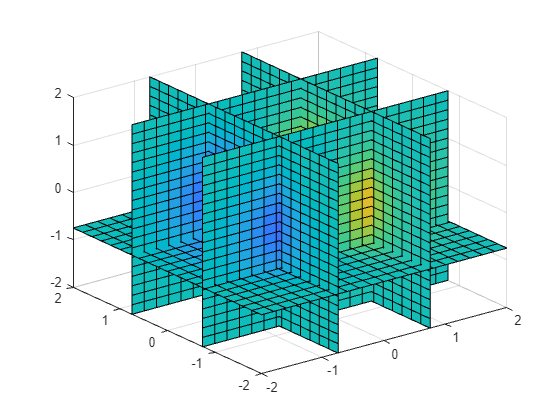

clear all
close all
figure(1)
[x,y,z] = meshgrid(-2:.2:2, -2:.2:2, -2:.2:2);
v = x .* exp(-x.^2 - y.^2 - z.^2);
slice(x,y,z,v,[-.75  .75  ],[-.75  .75],[-.75 ])

Another option is to use the isosurface command. Now, contour lines are really just 'isolines'. An iso-surface is just a higher-dimension version of this. You are simply plotting surfaces that have the save value of the variable you are considering. Below is an example where I plot two surfaces. You have to experiment to see what works best...

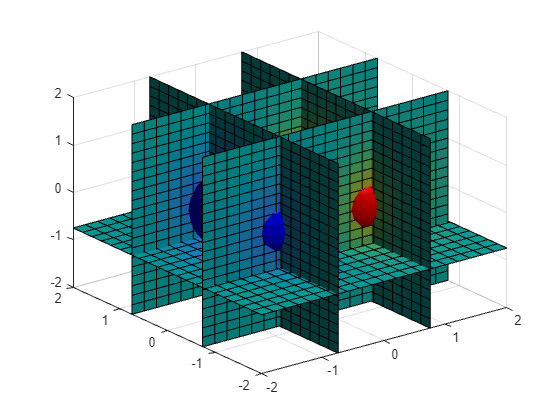

figure(2)
FV=isosurface(x,y,z,v,.2);
p=patch(FV);
isonormals(x,y,z,v,p);
p.FaceColor='red';
p.EdgeColor = 'none';

view(3)
camlight; lighting phong
%hold on
FV2=isosurface(x,y,z,v,-.2);
p2=patch(FV2);
isonormals(x,y,z,v,p2);
p2.FaceColor='blue';
p2.EdgeColor = 'none';
axis([-2 2 -2 2 -2 2])
grid on

## Bubble Plots

One of your classmates specifically asked about bubble plots in matlab. Bubble charts are generally used to show relationships between three variables in 2-d space. The 3rd variable is used to (i) size the bubble, (ii) color the bubble, or (iii) both. Here is a simple example: 

x = 1:20;
y = rand(1,20);
sz = rand(1,20);
bubblechart(x,y,sz);

In the above example, we adjust the size based on the variable sz. But, we don't adjust the color. We could do that too:

c = 1:20;
bubblechart(x,y,sz,c) 

Note that there is a 3d version of bubblechart, but I find it a bit unhelpful visually. You may like it better than me...Also note. You can much of the same thing by just using scatter. However, it is more fiddly if you want to easily control the size. Bubblechart is a much superior option.

scatter(x,y,50,c, "filled"); box on  